## Interpolation, Smoothing and Fourier Spectra

This notebook includes some exercises to related to interpolaton, smooth and fourier transforms in MATLAB. Prepared for EAS Practical Coding and Math course at Georgia Tech.

Load in and plot Atlanta mean temperature data

data=load('ATL_MonMeanTemp_1879_2020.mat');
data = data.ATLtemp;
year = data(:,1);
N=length(year)*12;
time=year(1)+(0:N-1)./12; %create a vector time coordinate
alltemp = data(:,2:end)';
alltemp = alltemp(:); %unwrap data into a vector of all temps

Plot all temperature data

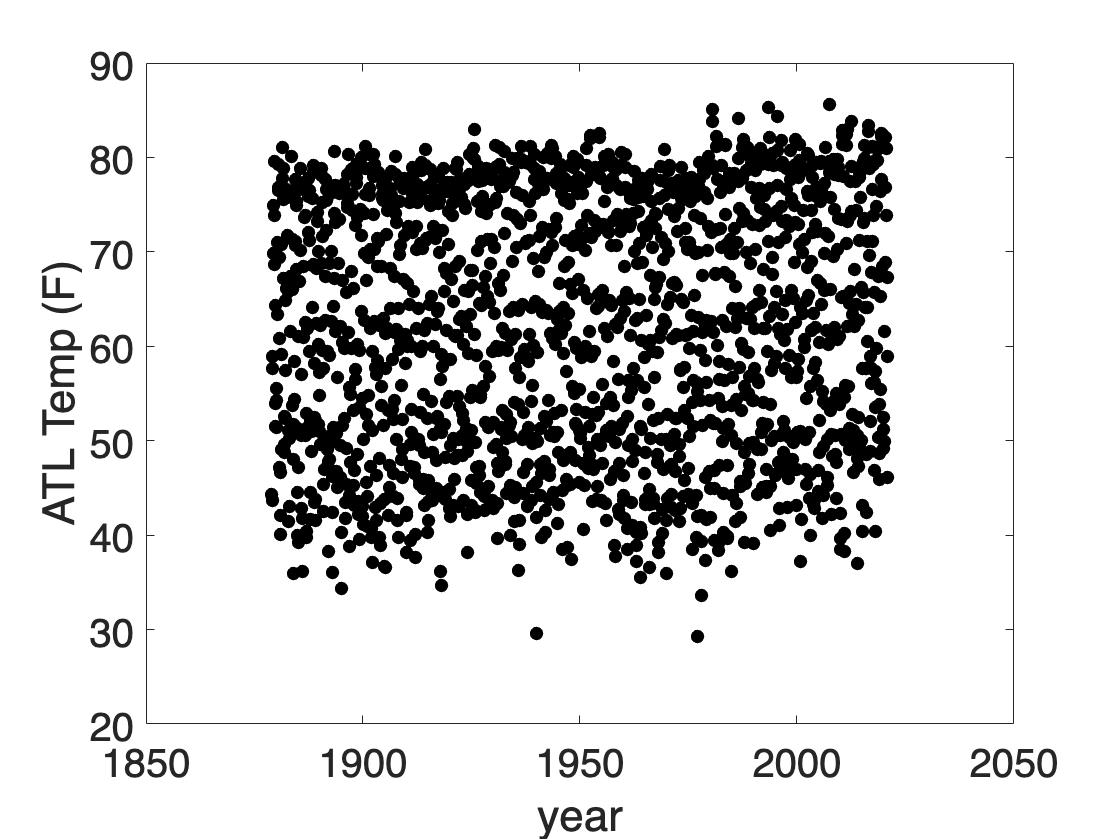

figure;plot(time,alltemp,'k.','markersize',20)
ylabel(['ATL Temp (F)'],'fontsize',20)
xlabel('year','fontsize',20)
set(gca,'fontsize',20)

### Interpolation and Smoothing

Lets pretend for a moment that we have data at irregular intervals, and we instead need it on a regular sampling interval. We can interpolate from the irregular to the regular interval using the interp1 function in MATLAB

randints = unique([1;randperm(N,floor(N/4))';N]);
temp_irreg = alltemp(randints);
time_irreg = time(randints);
temp_interp_monthly = interp1(time_irreg,temp_irreg,time); 

 Now plot interpolated data

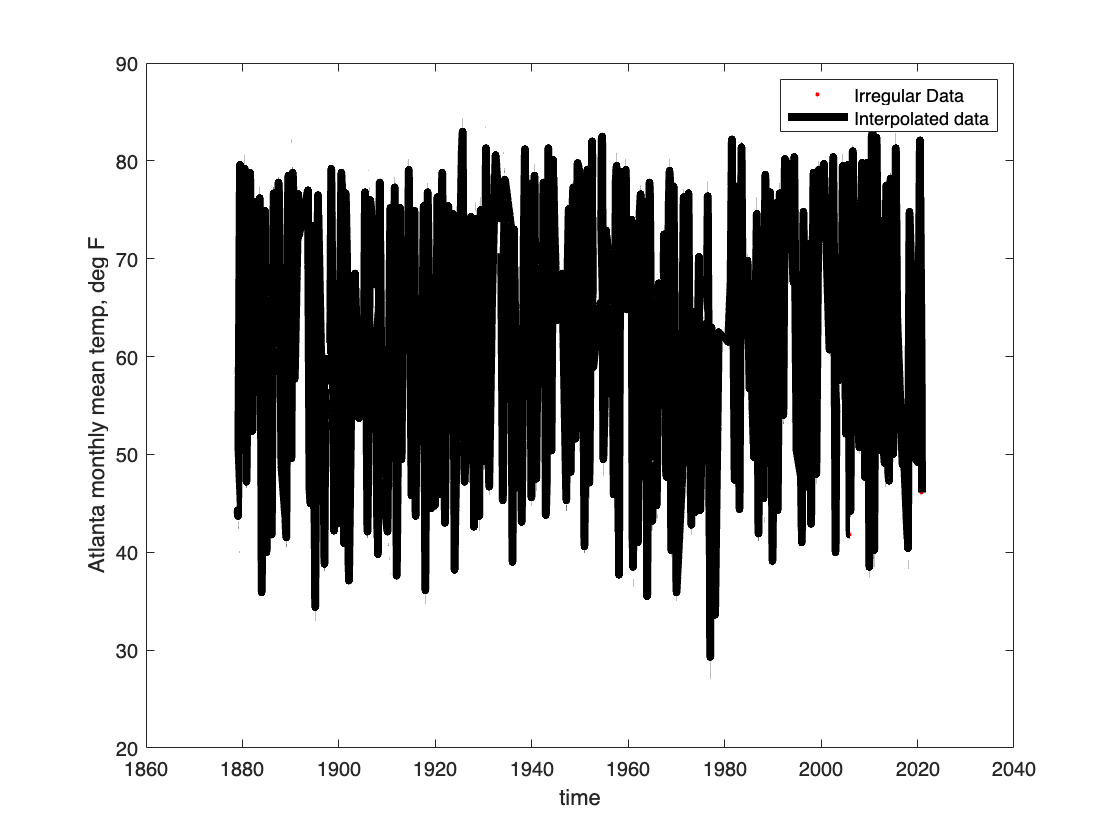

plot(time_irreg,temp_irreg,'r.');hold on
plot(time,temp_interp_monthly,'k-','linewidth',4)
xlabel('time')
ylabel('Atlanta monthly mean temp, deg F')
legend('Irregular Data','Interpolated data')

But zooming in one can see that this sort of linear interpolation leads to problems

ind = time>2000

ind = 1×1704 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


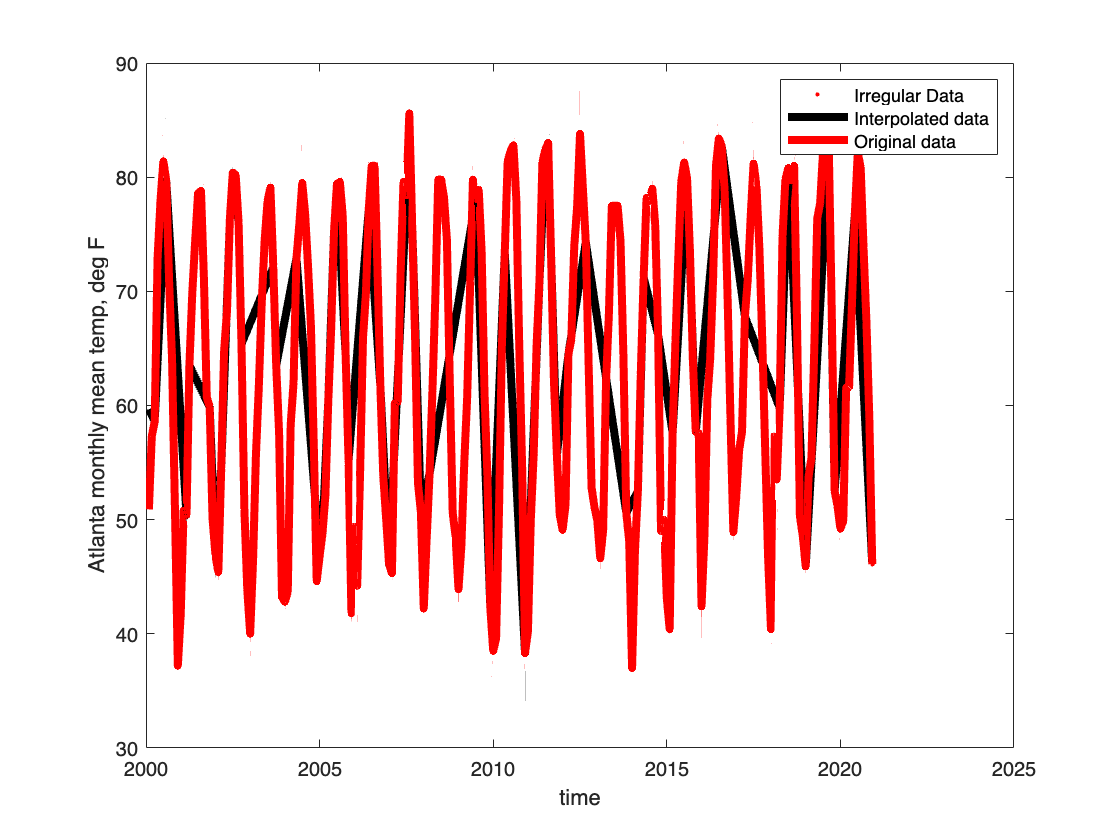

figure;
plot(time_irreg(time_irreg>2000),temp_irreg(time_irreg>2000),'r.');hold on
plot(time(ind),temp_interp_monthly(ind),'k-','linewidth',4)
plot(time(ind),alltemp(ind),'r-','linewidth',4)
xlabel('time')
ylabel('Atlanta monthly mean temp, deg F')
legend('Irregular Data','Interpolated data','Original data')

### Smoothing

Lets say now that I wanted to do some smoothing from data that was very noisy. The most basic kind of smoothing is a boxcar (moving average). MATLAB has a built in function called smoothdata that will allow you to smooth 1D data in various ways. You can also use convolutions with a smoothing kernel (as in python) to smooth, but we won't cover that here.

temp_boxfilt = smoothdata(alltemp,"movmean",12); %input data, method, window size

This is a 12-month boxcar window filter, which removes all the seasonality in temperature (averages over a year's worth of data), but it has problems near the edges of the data

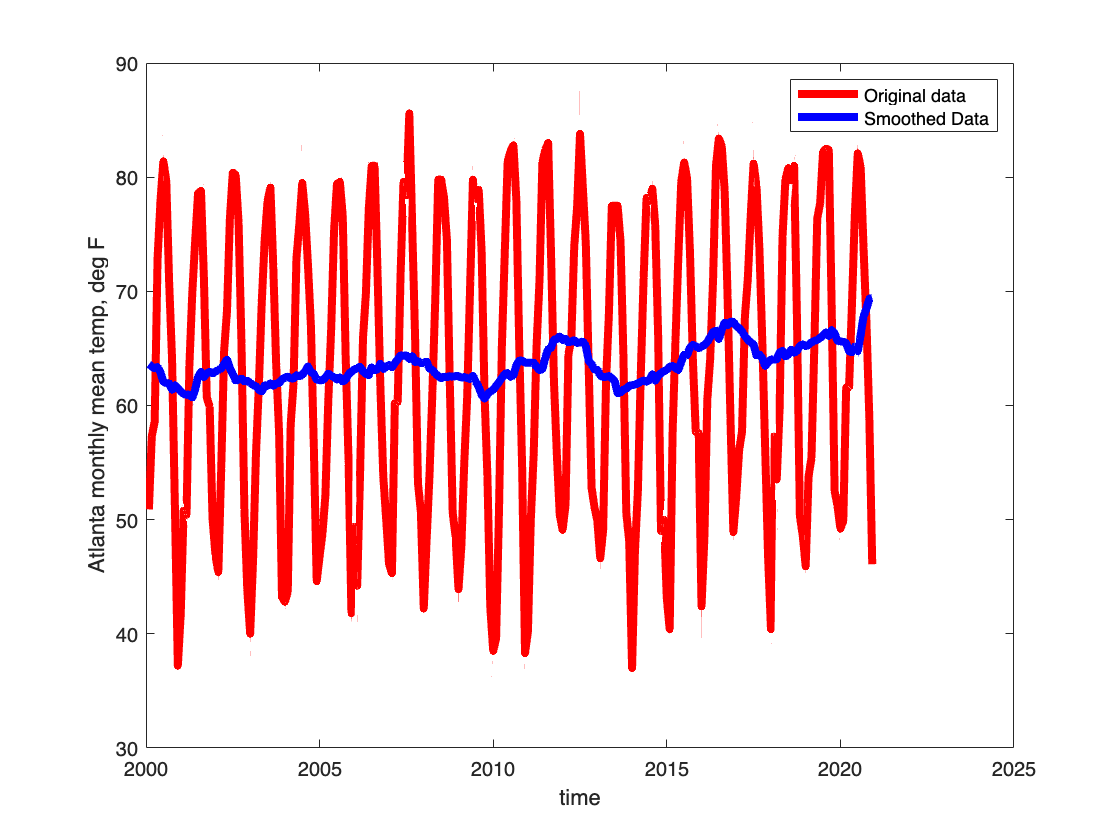

figure;
plot(time(ind),alltemp(ind),'r-','linewidth',4);hold on
plot(time(ind),temp_boxfilt(ind),'b-','linewidth',4)
xlabel('time')
ylabel('Atlanta monthly mean temp, deg F')
legend('Original data','Smoothed Data')

Data filtered in this way is useful for separating seasonality or other periodic signals from non-periodic signals, common in Earth Sci

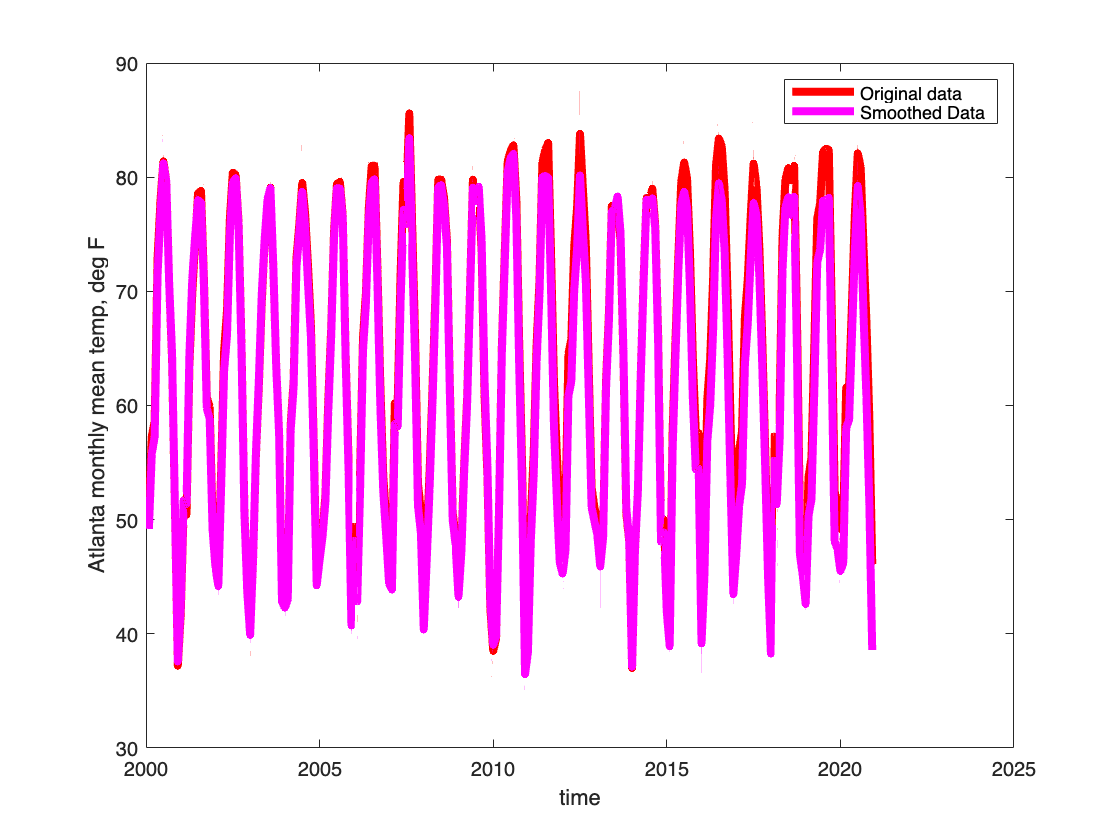

figure;
plot(time(ind),alltemp(ind),'r-','linewidth',4);hold on
plot(time(ind),alltemp(ind)-temp_boxfilt(ind) + mean(alltemp),'m-','linewidth',4)
xlabel('time')
ylabel('Atlanta monthly mean temp, deg F')
legend('Original data','Smoothed Data')

Or you could just calculate an annual climatology from the original formatted data

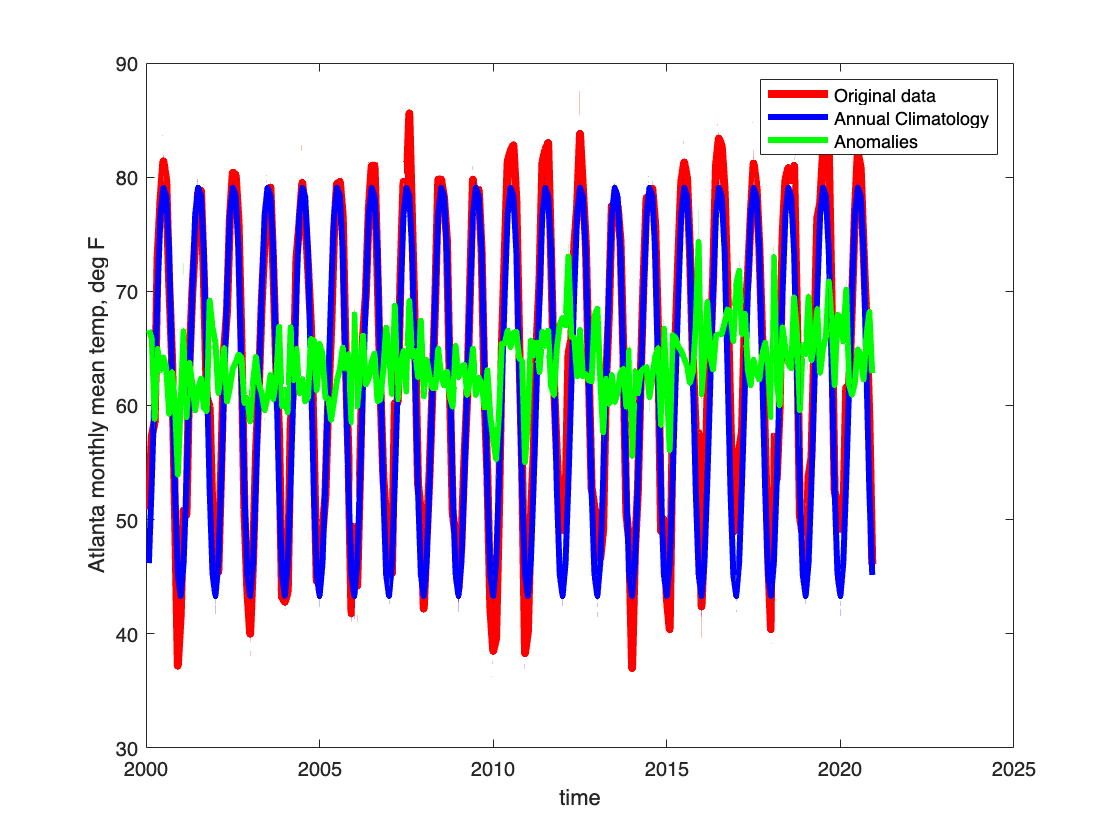

temp_clim = mean(data(:,2:end))';
temp_clim = repmat(temp_clim,[floor(N/12) 1]);
temp_climanom = alltemp(:) - temp_clim;

figure;
plot(time(ind),alltemp(ind),'r-','linewidth',4);hold on
plot(time(ind),temp_clim(ind),'b-','linewidth',3)
plot(time(ind),alltemp(ind)-temp_clim(ind)+ mean(alltemp),'g-','linewidth',3)
xlabel('time')
ylabel('Atlanta monthly mean temp, deg F')
legend('Original data','Annual Climatology','Anomalies')

### Fourier Spectra

We can use the fft library in numpy to calculate fourier coefficients efficiently. First subtract the long term mean temperature from ATL data and set sampling frequency

temp_anom= alltemp - mean(alltemp);
c = fft(temp_anom);
Nc = length(c);

dt = 1/12;
T = N*dt; %period in the units of years

Calculate frequencies corresponding to fft coefficients and plot

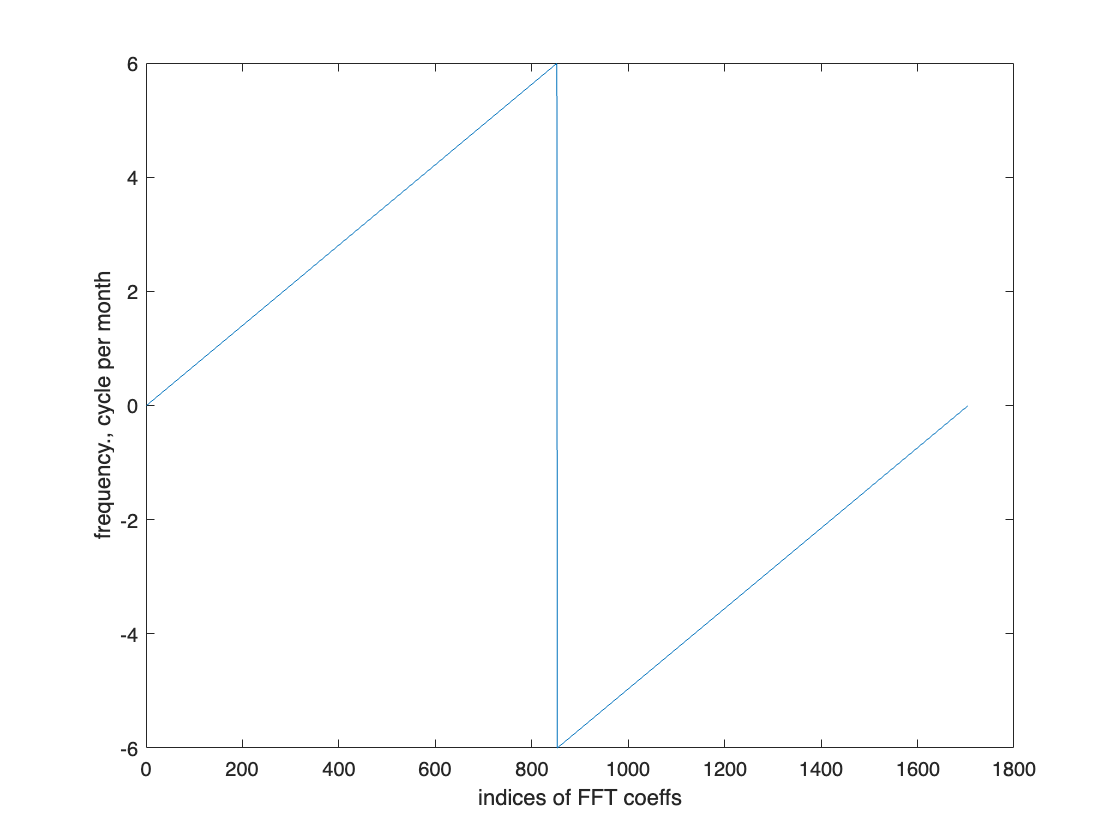

Fs = 1/dt;
df = Fs/N;
freq = [0:df:Fs/2-df,-Fs/2:df:-df];
per = 1./freq;

figure
plot(freq)
ylabel('frequency., cycle per month')
xlabel('indices of FFT coeffs')

Now plot the power spectral density

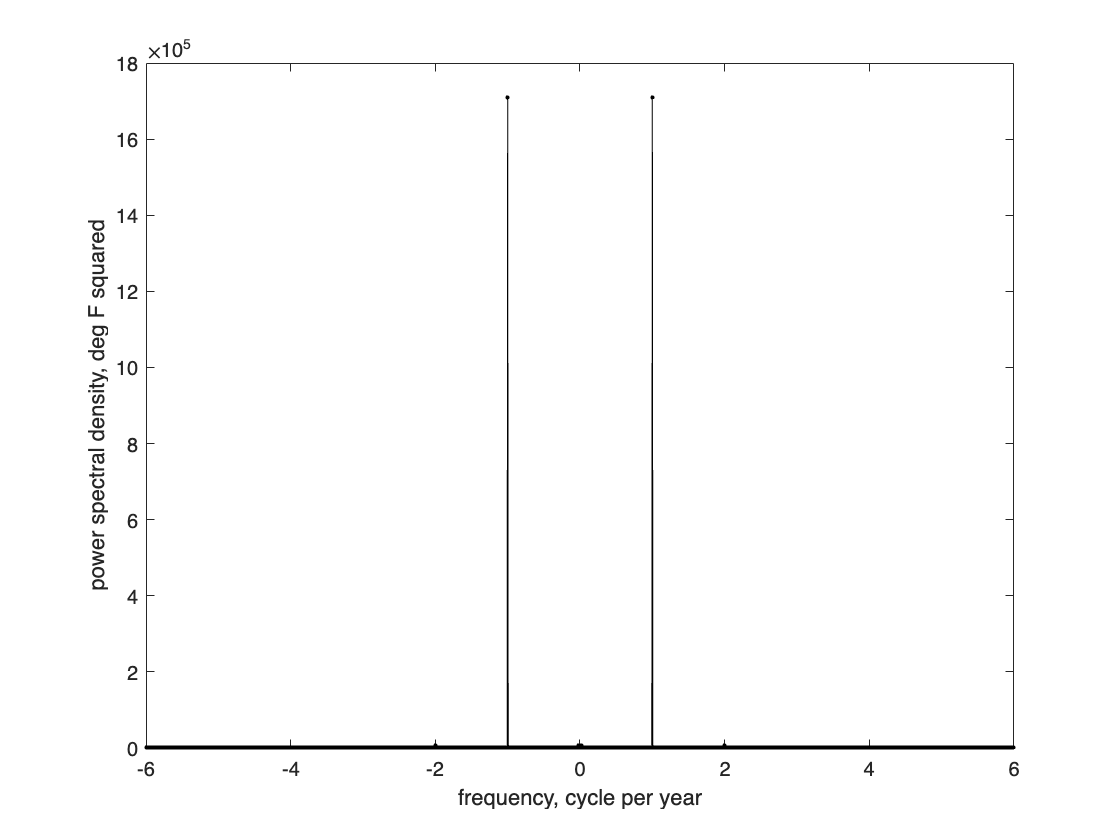

plot(freq,abs(c).^2/(N*dt),'k.-')
ylabel('power spectral density, deg F squared')
xlabel('frequency, cycle per year')

Just taking the 1/2 of the data and multiply by 2

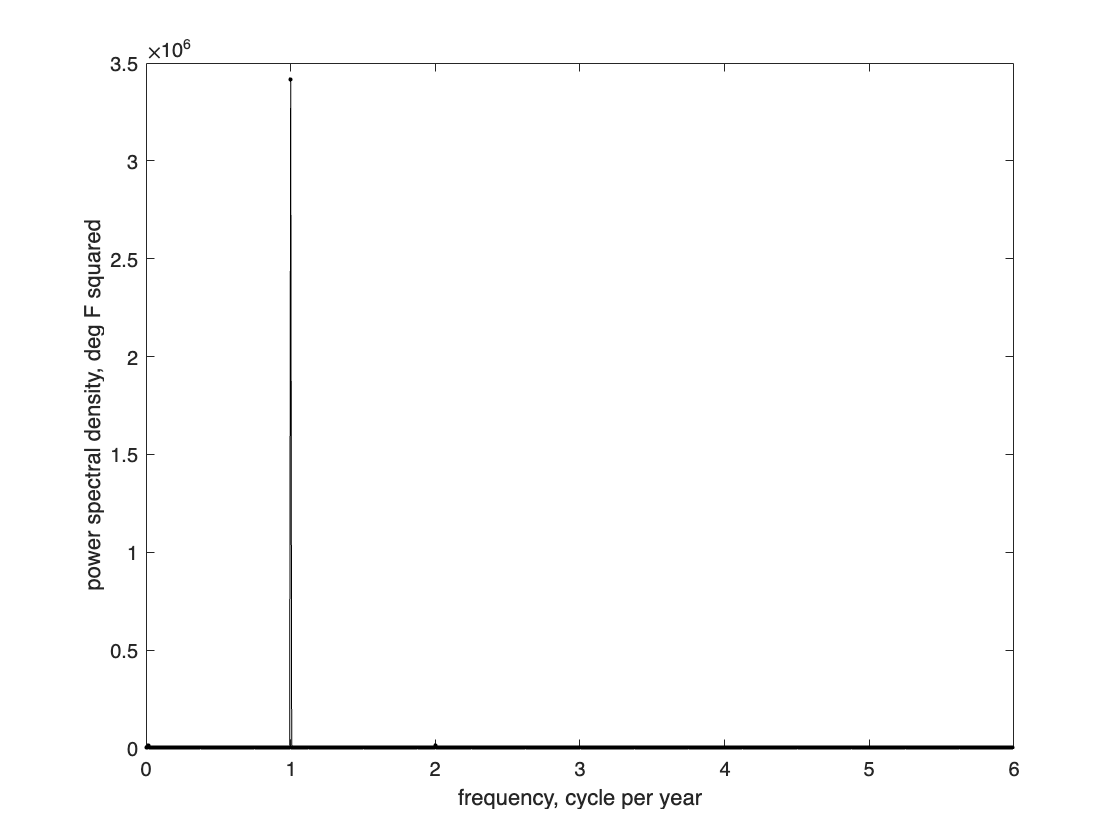

figure;
plot(freq(1:floor(N/2)),2*abs(c(1:floor(N/2))).^2/(N*dt),'k.-')
ylabel('power spectral density, deg F squared')
xlabel('frequency, cycle per year')

Inverse FFT to go back to real space and plot

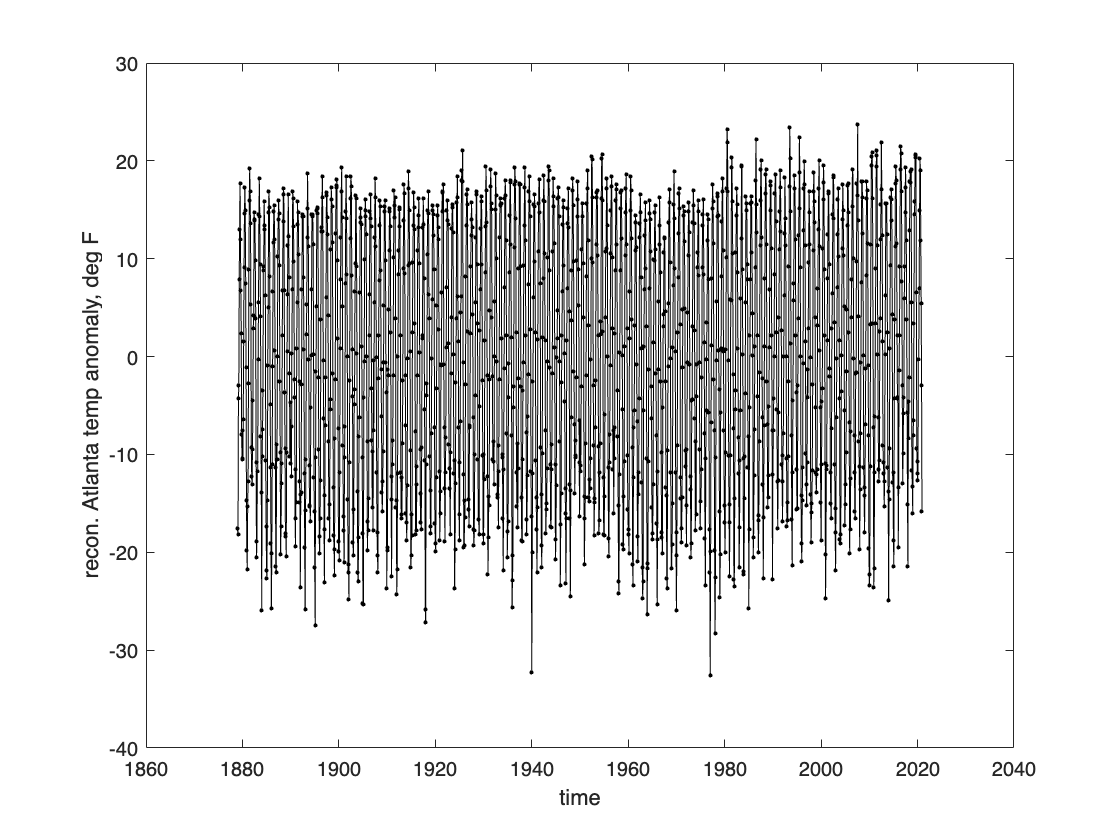

data_reconstructed = ifft(c);
plot(time,data_reconstructed,'k.-')
xlabel('time')
ylabel('recon. Atlanta temp anomaly, deg F')

We can also use the fft to filter out specific frequencies or ranges of frequencies from the data and plot the resulting PSD

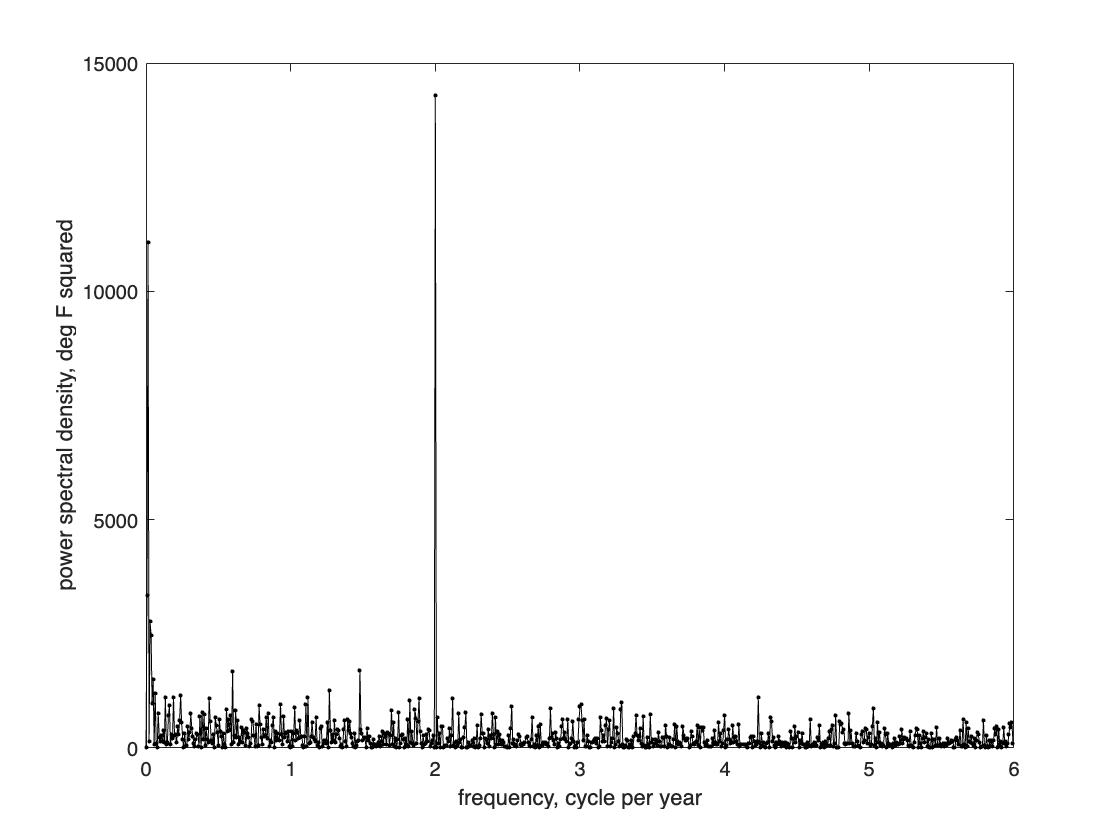

seas = abs(freq)==1; %Filter out seasonality, frequency = 1
c_filt = c; %copy the Fourier coefficient
c_filt(seas)=0; %remove the seasonal cycle

plot(freq(1:floor(N/2)),2*abs(c_filt(1:floor(N/2))).^2/(N*dt),'k.-')
ylabel('power spectral density, deg F squared')
xlabel('frequency, cycle per year')

Now use inverse FFT to go back to time domain and plot the result

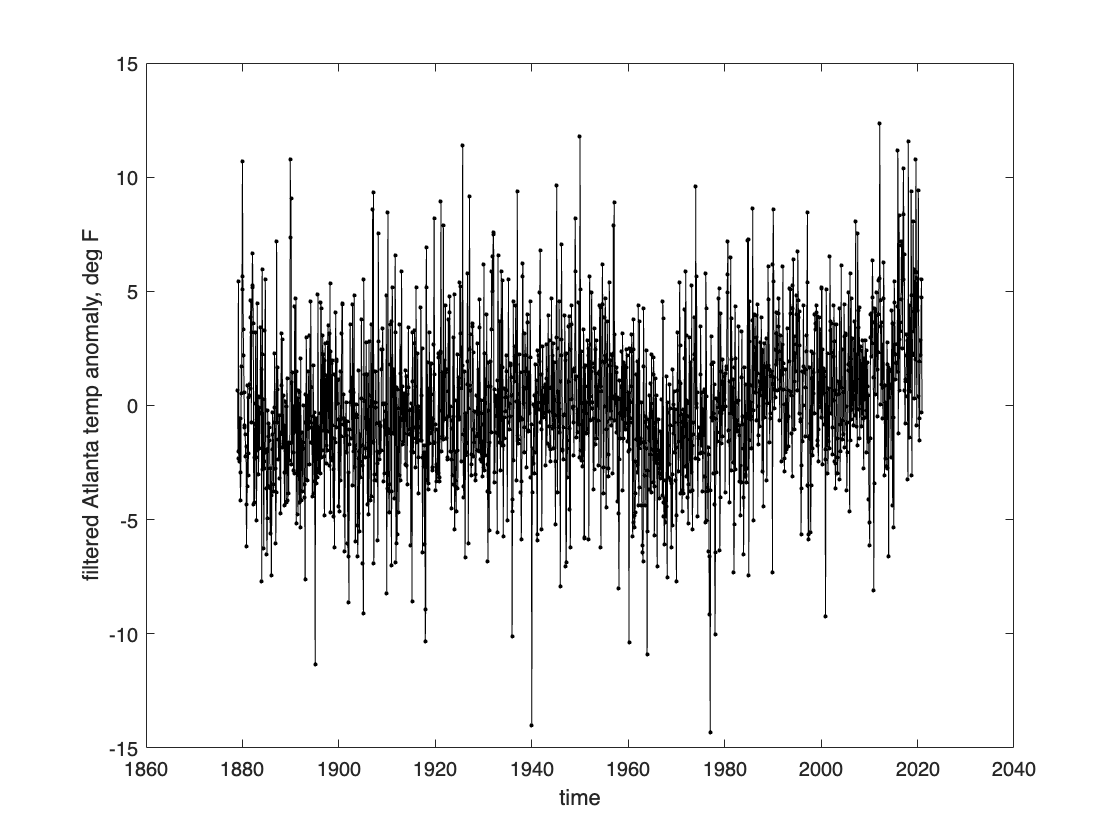

data_filt = ifft(c_filt);

plot(time,data_filt,'k.-')
xlabel('time')
ylabel('filtered Atlanta temp anomaly, deg F')

One could also think about creating a "surrogate" of this time series by randomizing the phases of the fourier coefficients (imaginary components) and then performing an inverse fourier transform, turning it into a time series with the same frequency content, but just at random phases

c_filt_rphase = real(c_filt) + (2*pi)*rand(length(c_filt),1)*i;

data_filt_rphase = ifft(c_filt_rphase);

plot(time,data_filt_rphase,'k.-')

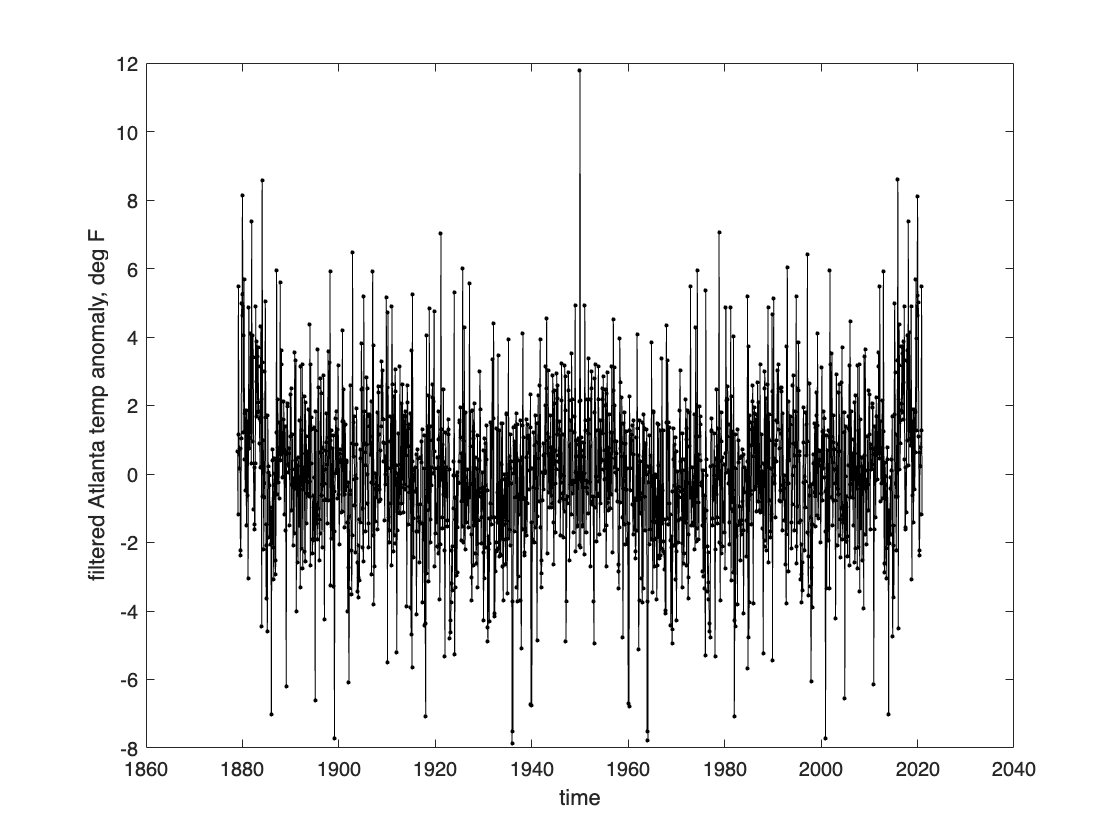

xlabel('time')
ylabel('filtered Atlanta temp anomaly, deg F')

We can also filter out all the high frequency variability at less than 2 years period

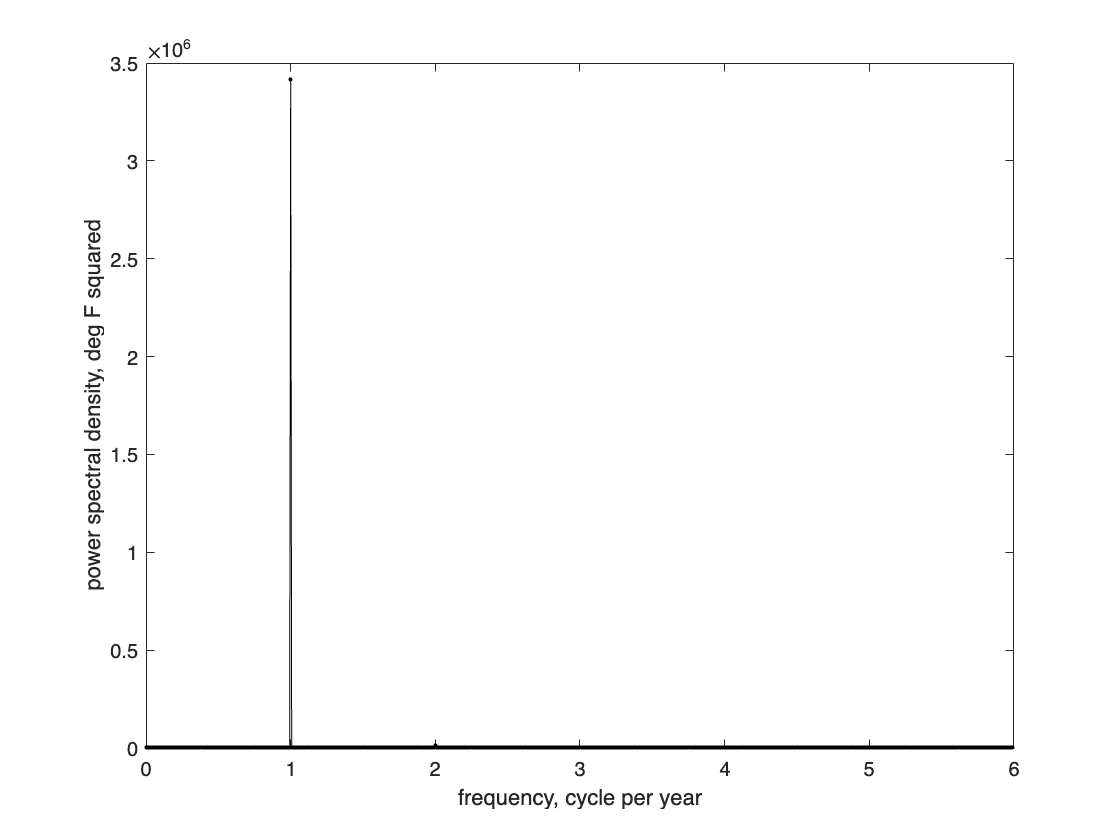

hf = abs(freq)<=1/2; %Apply filter 
c_filt = c; %copy the Fourier coefficient
c_filt(hf) = 0; %remove the seasonal cycle

plot(freq(1:floor(N/2)),2*abs(c_filt(1:floor(N/2))).^2/(N*dt),'k.-')
ylabel('power spectral density, deg F squared')
xlabel('frequency, cycle per year')

Then invert and plot result

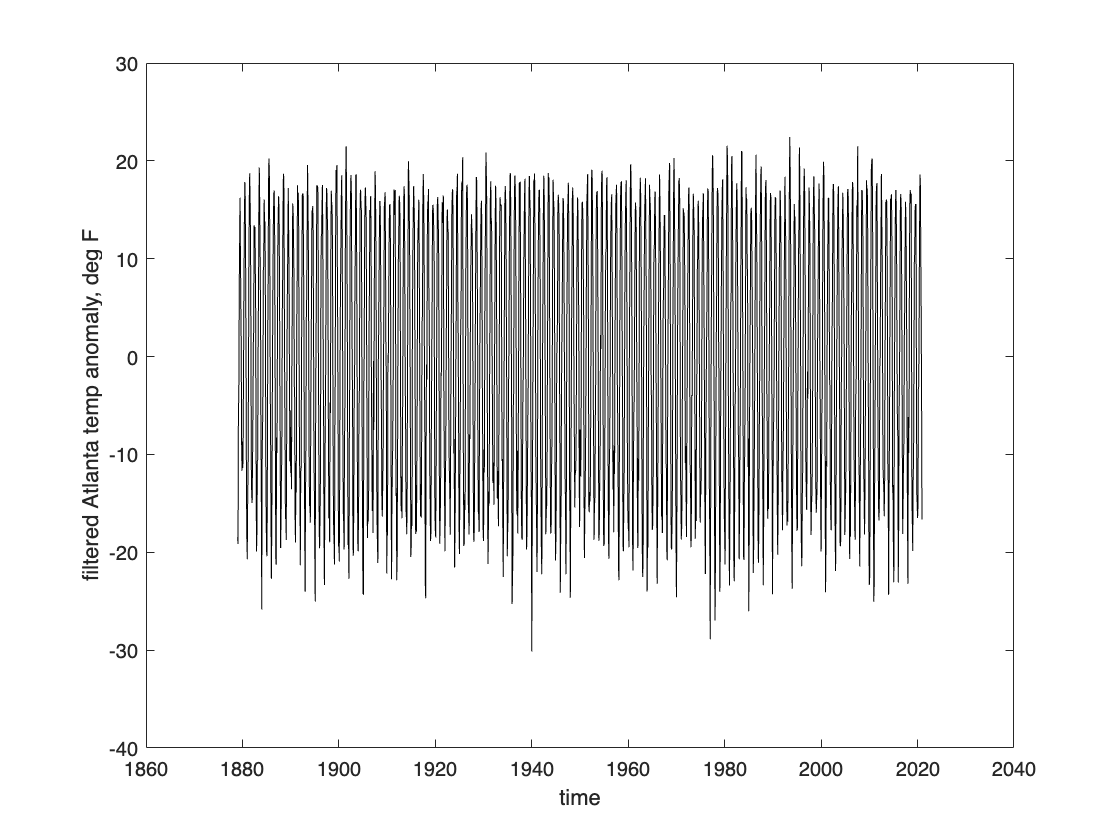

data_filt = ifft(c_filt);

plot(time,data_filt,'k-')
xlabel('time')
ylabel('filtered Atlanta temp anomaly, deg F')